# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.10 Spotlight Point Spread Function

## Calculate the spectral support (m)

% Clear the workspace
clear

% Slant range (m)
slant_range = 100;

% Synthetic aperture length (m)
aperture_length = 1000;

% Point target location (m)
x_target = 10;
y_target = 5;

% Speed of light
% c = physconst('Lightspeed');
c = 299792458;

% Waveform bandwidth (Hz)
waveform_bandwidth = 50e6;

% Operating frequency (Hz)
operating_frequency = 1e9;

% Calculate the min and max wavelengths
wavelength_min = c / (operating_frequency + 0.5 * waveform_bandwidth);
wavelength_max = c / (operating_frequency - 0.5 * waveform_bandwidth);

% Calculate the min and max wavenumber
kmin = 2 * pi / wavelength_max;
kmax = 2 * pi / wavelength_min;
kc = c / operating_frequency;

% Calculate the angles at the endpoints of the synthetic aperture (rad)
theta_minus = atan((0.5 * aperture_length - y_target) / (slant_range + x_target));
theta_plus  = atan((0.5 * aperture_length + y_target) / (slant_range + x_target));
if x_target == 0
    theta_zero = 0;
else
    theta_zero  = atan(y_target / (x_target + slant_range));
end

% Calculate the spectral support (rad/m) Equations (2.32) and (2.33)
dkx = 2 * (kmax - kmin);
dky = 2 * kc * (sin(theta_plus) + sin(theta_minus));

% Rotation matrix
R = [cos(theta_zero) -sin(theta_zero); sin(theta_zero) cos(theta_zero)];

## Calculate the point spread function

$\textrm{psf}=\textrm{sinc}\left(\frac{\Delta \;k_x^{\prime } x^{\prime } \;}{2\;\pi \;}\right)\textrm{sinc}\left(\frac{\Delta \;k_y^{\prime } y^{\prime } \;}{2\pi \;}\right)$   Equation (2.34)

% Set up the x and y grid
x = linspace(-20, 20, 1e3);
y = linspace(-20, 20, 1e3);

[xs, ys] = meshgrid(x, y);

% Get the rotated mesh
xp = zeros(1000, 1000);
yp = zeros(1000, 1000);

for i = 1:1000
    for j = 1:1000
        a = [xs(i,j) - x_target, ys(i, j) - y_target] * R;
        xp(i,j) = a(1); yp(i,j) = a(2);
    end
end

% Calculate the PSF
psf = sinc(dkx * xp / (2 * pi)) .* sinc(dky * yp / (2 * pi));

## Plot the results

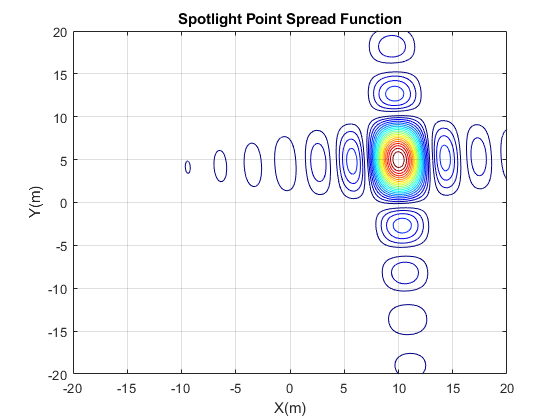

figure;
contour(xs, ys, abs(psf), 20);
colormap jet;
xlabel('X(m)')
ylabel('Y(m)')
title('Spotlight Point Spread Function')
grid on;